### Orientation Evolution

with Quaternions

% Example 1 - Solving for orientation mid way from Ri to Rf
% Initial orientation
Ri = eye(3)

Ri =      1     0     0
     0     1     0
     0     0     1


% Final orientation
Rf =[0.8470 -0.3705 -0.3813;
     0.5152 0.3949 0.7607;
     0.1313 -0.8407 0.5253]

Rf =     0.8470   -0.3705   -0.3813
    0.5152    0.3949    0.7607
    0.1313   -0.8407    0.5253


% Solving for rotation matrix to get from Ri to Rf
R = Ri^(-1) * Rf

R =     0.8470   -0.3705   -0.3813
    0.5152    0.3949    0.7607
    0.1313   -0.8407    0.5253


% Converting R into HTM
T = HTM(R)

T =     0.8470   -0.3705   -0.3813         0
    0.5152    0.3949    0.7607         0
    0.1313   -0.8407    0.5253         0
         0         0         0    1.0000


% Converting both HTM into Quaternions
Q = to_quaternion(T)

Q =   Quaternion with properties:

    Vector: [0.8317 -0.4814 -0.0752 0.2662]


% Solving for theta (rotation from Ri to Rf in radians)
theta = acos(Q.Vector(1))*2

theta = 1.1771

% Solving for k (unitarian vector of rotation vector from Ri to Rf)
k = Q.Vector(1,2:end)/sin(theta/2)

k =    -0.8671   -0.1354    0.4795


% Mid way orientation
thetaj = theta*0.5

thetaj = 0.5886

% Solving for rotation quaternion at thetaj
Qj = Quaternion(k, thetaj)

Qj =   Quaternion with properties:

    Vector: [0.9570 -0.2515 -0.0393 0.1391]


% Solving for transformation matrix at thetaj
Tj = HTM(Ri) * to_HTM(Qj)

Tj =     0.9582   -0.2464   -0.1451         0
    0.2859    0.8348    0.4704         0
    0.0052   -0.4923    0.8704         0
         0         0         0    1.0000


% Solving for rotation matrix at thetaj
Rj = Tj(1:3,1:3)

Rj =     0.9582   -0.2464   -0.1451
    0.2859    0.8348    0.4704
    0.0052   -0.4923    0.8704


% Example 2 - Represent what rotation R1 experiments until it reaches ([1 1 1], pi/2)
% Initial orientation
R1 = [-1 0 0; 0 1 0; -1e-16 0 -1]

R1 =    -1.0000         0         0
         0    1.0000         0
   -0.0000         0   -1.0000


% Solving for final orientation R2
u = [1 1 1];
theta = pi/2;
k2 = 1/norm(u) * [1 1 1];
 
Q2 = Quaternion(k2, theta);
T2 = to_HTM(Q2);

R2 = T2(1:3,1:3)

R2 =     0.3333   -0.2440    0.9107
    0.9107    0.3333   -0.2440
   -0.2440    0.9107    0.3333


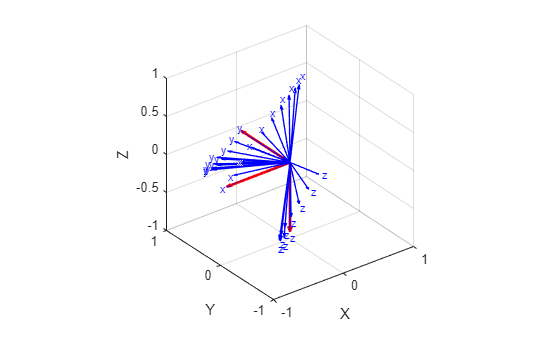

% Solving for rotation quaternion to rotate from Ri to Rf
R = R1^(-1) * R2;
T = HTM(R);
Q = to_quaternion(T);
theta = acos(Q.Vector(1))*2;
k = Q.Vector(1,2:end)/sin(theta/2);

% Ploting orientation evolution
T1 = HTM(R1);
Q1 = to_quaternion(T1);

x = Quaternion([0 1 0 0]); y = Quaternion([0 0 1 0]); z = Quaternion([0 0 0 1]); o = [0 0 0];
x_prime = Q1 * x * Q1.conjugate();
y_prime = Q1 * y * Q1.conjugate();
z_prime = Q1 * z * Q1.conjugate();

figure;
hold on;
quiver3(o, o, o, x_prime.Vector(2:end), y_prime.Vector(2:end), z_prime.Vector(2:end), ...
    'r', 'LineWidth', 2, 'MaxHeadSize',0.2);
grid on; axis equal;
xlim([-1 1]); ylim([-1 1]); zlim([-1 1]);
xlabel('X'); ylabel('Y'); zlabel('Z'); view(3);

x = x_prime; y = y_prime; z = z_prime;

for thetaj = linspace(0,theta,10)
    Qj = Quaternion(k, thetaj);
    x_prime = Qj * x * Qj.conjugate();
    y_prime = Qj * y * Qj.conjugate();
    z_prime = Qj * z * Qj.conjugate();

    quiver3(o, o, o, x_prime.Vector(2:end), y_prime.Vector(2:end), z_prime.Vector(2:end), ...
    'b', 'LineWidth',1, 'MaxHeadSize',0.15);
    text(x_prime.Vector(2), y_prime.Vector(2), z_prime.Vector(2), 'x', 'FontSize',8, 'Color','b');
    text(x_prime.Vector(3), y_prime.Vector(3), z_prime.Vector(3), 'y', 'FontSize',8, 'Color','b');
    text(x_prime.Vector(4), y_prime.Vector(4), z_prime.Vector(4), 'z', 'FontSize',8, 'Color','b');
end
hold off;